% For 1D
a = [-3];
b = [3];
n_samples = 100000;
d = 1;

integrand_func = func1(d);
integral_estimate = monte_carlo_integration(integrand_func, a, b, n_samples);
disp(['The MC estimated integral for function 1 in 1D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 1 in 1D is: 0.99534


a = [0];
b = [1];

integrand_func = func2(d);
integral_estimate = monte_carlo_integration(integrand_func, a, b, n_samples);
disp(['The MC estimated integral for function 2 in 1D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 2 in 1D is: 0.99968



integrand_func = func3(d);
integral_estimate = monte_carlo_integration(integrand_func, a, b, n_samples);
disp(['The MC estimated integral for function 3 in 1D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 3 in 1D is: 11.9185



integrand_func = func4(d);
integral_estimate = monte_carlo_integration(integrand_func, a, b, n_samples);
disp(['The MC estimated integral for function 4 in 1D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 4 in 1D is: 0.19125



integrand_func = func5(d);
integral_estimate = monte_carlo_integration(integrand_func, a, b, n_samples);
disp(['The MC estimated integral for function 5 in 1D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 5 in 1D is: 0.4998



integrand_func = func6(d);
integral_estimate = monte_carlo_integration(integrand_func, a, b, n_samples);
disp(['The MC estimated integral for function 6 in 1D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 6 in 1D is: 0.16681


% For 2D
d = 2;
a = [-3, -3]; 
b = [3, 3];
num_samples = 100000; 

integrand_func = func1(d);
integral_estimate = monte_carlo_integration(integrand_func, a, b, num_samples);
disp(['The MC estimated integral for function 1 in', num2str(d), '-D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 1 in2-D is: 0.99979


a = [0, 0]; 
b = [1, 1];

integrand_func = func2(d);
integral_estimate = monte_carlo_integration(integrand_func, a, b, num_samples);
disp(['The MC estimated integral for function 2 in', num2str(d), '-D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 2 in2-D is: 0.99953



integrand_func = func3(d);
integral_estimate = monte_carlo_integration(integrand_func, a, b, num_samples);
disp(['The MC estimated integral for function 3 in', num2str(d), '-D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 3 in2-D is: 141.9171



integrand_func = func4(d);
integral_estimate = monte_carlo_integration(integrand_func, a, b, num_samples);
disp(['The MC estimated integral for function 4 in', num2str(d), '-D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 4 in2-D is: -0.015841



integrand_func = func5(d);
integral_estimate = monte_carlo_integration(integrand_func, a, b, num_samples);
disp(['The MC estimated integral for function 5 in', num2str(d), '-D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 5 in2-D is: 0.24989



integrand_func = func6(d);
integral_estimate = monte_carlo_integration(integrand_func, a, b, num_samples);
disp(['The MC estimated integral for function 6 in', num2str(d), '-D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 6 in2-D is: 0.015182


% For 3D
d = 3;
a = [-3, -3, -3]; 
b = [3, 3, 3];
num_samples = 100000; 

integrand_func = func1(d); 
integral_estimate = monte_carlo_integration(integrand_func, a, b, num_samples);
disp(['The MC estimated integral for function 1 in', num2str(d), '-D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 1 in3-D is: 0.99166


a = [0, 0, 0]; 
b = [1, 1, 1];

integrand_func = func2(d); 
integral_estimate = monte_carlo_integration(integrand_func, a, b, num_samples);
disp(['The MC estimated integral for function 2 in', num2str(d), '-D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 2 in3-D is: 0.99424



integrand_func = func3(d); 
integral_estimate = monte_carlo_integration(integrand_func, a, b, num_samples);
disp(['The MC estimated integral for function 3 in', num2str(d), '-D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 3 in3-D is: 1685.2407



integrand_func = func4(d); 
integral_estimate = monte_carlo_integration(integrand_func, a, b, num_samples);
disp(['The MC estimated integral for function 4 in', num2str(d), '-D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 4 in3-D is: -0.0007214



integrand_func = func5(d); 
integral_estimate = monte_carlo_integration(integrand_func, a, b, num_samples);
disp(['The MC estimated integral for function 5 in', num2str(d), '-D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 5 in3-D is: 0.12494



integrand_func = func6(d); 
integral_estimate = monte_carlo_integration(integrand_func, a, b, num_samples);
disp(['The MC estimated integral for function 6 in', num2str(d), '-D is: ', num2str(integral_estimate)]);

The MC estimated integral for function 6 in3-D is: 0.0009467


d = 3; % change dimension to calculate
a = [0, 0, 0]; 
b = [1, 1, 1];
tol = 1e-3;     % Tolerance for error

integrand_func = func6(d);
integrand_func_builtin = func6_for_builtin(d);

if d == 1
    builtin_integral = integral(integrand_func_builtin, a(1), b(1));
elseif d == 2
    builtin_integral = integral2(integrand_func_builtin, a(1), b(1), a(2), b(2));
elseif d == 3
    builtin_integral = integral3(integrand_func_builtin,a(1), b(1), a(2), b(2), a(3), b(3));
end

disp(num2str(builtin_integral));

0.00094697


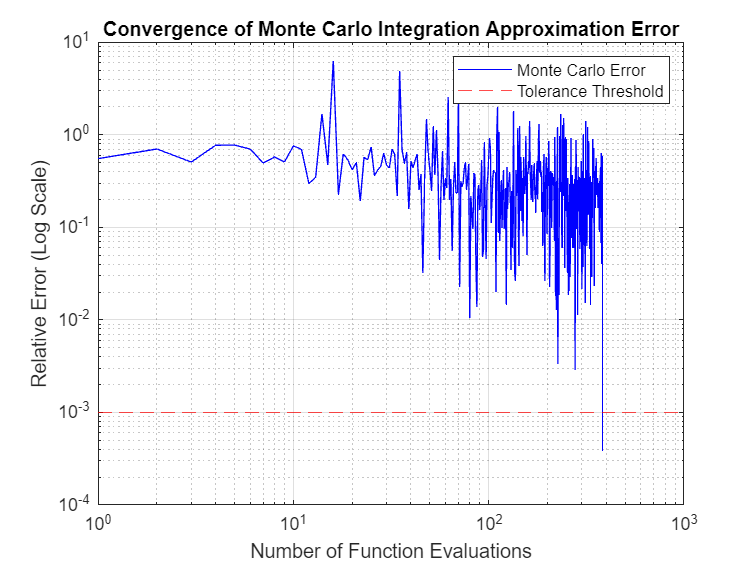


% Initialize variables for tracking
eva_size_MC = 1:10000;  % Number of function evaluations
errors_MC = zeros(size(eva_size_MC));  % Preallocate array for errors



func_evals_MC = zeros(size(eva_size_MC)); % To track function evaluations for Monte Carlo



% Monte Carlo integration loop
for i = 1:length(eva_size_MC)

    num_samples = eva_size_MC(i);
    [integral_estimate_MC, func_evals_MC(i)] = monte_carlo_integration(integrand_func, a, b, eva_size_MC(i));
    abs_diff = abs(builtin_integral - integral_estimate_MC);
    errors_MC(i) = abs_diff / abs(builtin_integral);
    

     % Check the error against the tolerance
     if errors_MC(i) < tol
         eva_size_MC = eva_size_MC(1:i);  % Trim the excess preallocated space
         errors_MC = errors_MC(1:i);  % Trim the excess preallocated space
         func_evals_MC = func_evals_MC(1:i);  % Trim the excess preallocated space
         break;  % Exit the loop if the error is below the tolerance
     end
end

figure;
loglog(func_evals_MC, errors_MC, 'b-', 'DisplayName', 'Monte Carlo Error');
hold on;
yline(tol, 'r--', 'DisplayName', 'Tolerance Threshold');
hold off;
xlabel('Number of Function Evaluations');
ylabel('Relative Error (Log Scale)');
title('Convergence of Monte Carlo Integration Approximation Error');
legend show;
grid on;




%-----------------------------------------------------------------------------------------------------------



Appendix

function [I, num_func_evals] = monte_carlo_integration(func, a, b, num_samples)
    % a is a vector of the lower limits of integration
    % b is a vector of the upper limits of integration
    % num_samples is the number of random samples to use for estimation
    % d is dimension
    
    % Check if the dimension of the limits matches
    if length(a) ~= length(b)
        error('The dimension of lower and upper limits must be the same.');
    end
    
    % Calculate the volume of the integration region
    volume = prod(b - a);
    
    % Generate random points within the integration limits
    % row vectors a and b
    random_points = bsxfun(@plus, a, bsxfun(@times, (b - a), rand(num_samples, numel(a))));
    
    % Evaluate the integrand at each random point
    % The integrand func should accept a matrix where each column is a point in d-dimensional space
    function_values = arrayfun(@(i) func(random_points(i, :)), 1:num_samples);
    
    % Estimate the integral
    I = volume * mean(function_values);
    
    % The number of function evaluations is the same as the number of samples
    num_func_evals = num_samples;
end